diff_deltaomega = 	1.0e+-5 *

    0.0037    0.2059   -0.3210


diff_E =    -0.0000    1.5000    1.1000
   -1.5000    0.0000   -0.4000
   -1.1000    0.4000    0.0000


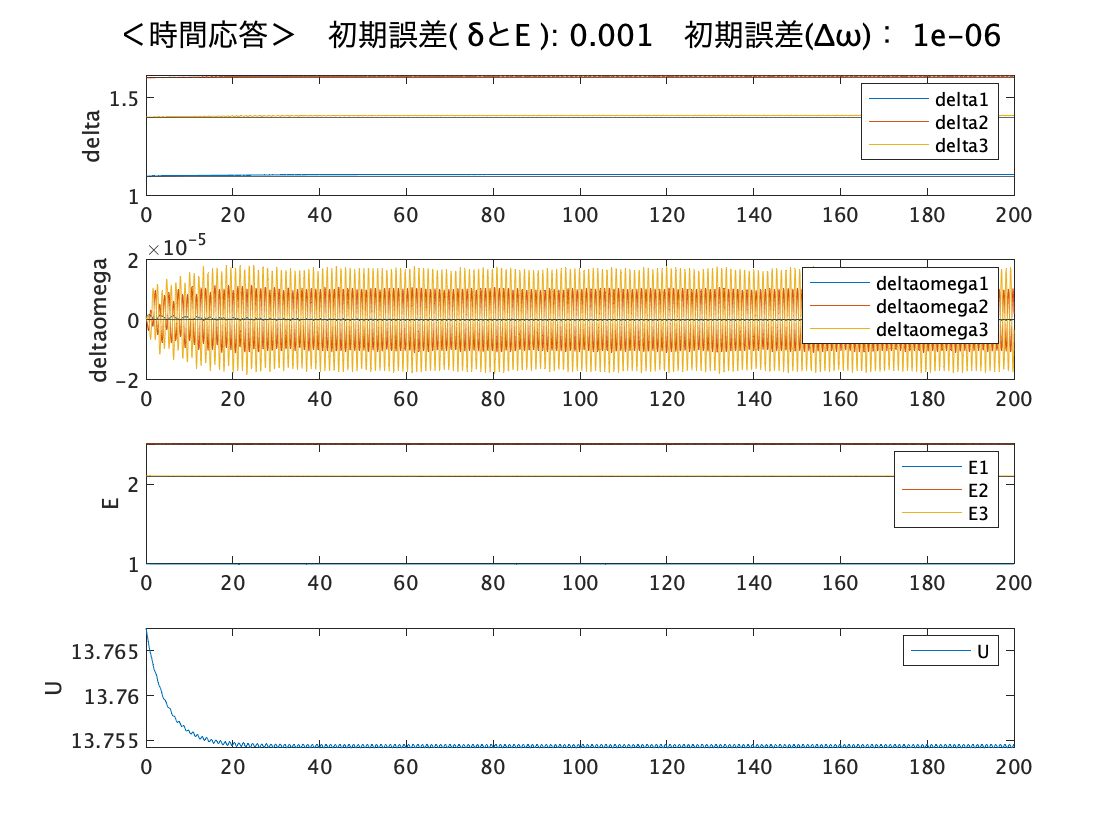

clear
tspan = [0 200];

%定常値を設定
steady_delta = [1.1;1.6;1.4];
steady_deltaomega = [0;0;0];
steady_E = [1;2.5;2.1];
steady_generator_state = [steady_delta; steady_deltaomega; steady_E];

plot_generator_state_wrap = @(cnt) plot_generator_state(cnt,tspan,steady_generator_state);

for rng = 0.001
    figure;
    t_U = plot_generator_state_wrap(rng);
    sgtitle(['＜時間応答＞　初期誤差( δとE ): ',num2str(rng), '　初期誤差(Δω)： ',num2str(rng*0.001)]);
end

figure;
f = fit(t_U(:,1),t_U(:,2),'poly4');
syms x f1(x) diff2_f1(x)
f1(x) = f.p1*x^4 + f.p2*x^3 + f.p3*x^2 + f.p4*x + f.p5;
diff2_f1(x) = diff(f1,2);
diff2_f1(1:10)  %任意のxで W(x)>=0 

$$ans = \left(\begin{array}{cccccccccc} \frac{89291793563021237623}{9671406556917033397649408} & \frac{21889989591030539767}{2417851639229258349412352} & \frac{85843534045370314543}{9671406556917033397649408} & \frac{5258907537922856503}{604462909807314587353088} & \frac{82456918048308327583}{9671406556917033397649408} & \frac{20196681592499546287}{2417851639229258349412352} & \frac{79131945571835276743}{9671406556917033397649408} & \frac{1210821494590931287}{151115727451828646838272} & \frac{75868616615951162023}{9671406556917033397649408} & \frac{18565017114557488927}{2417851639229258349412352} \end{array}\right)$$

F = solve(diff2_f1 == 0, x)  %かつ、これがあるxの範囲で複素数または解を持たないなら、蓄積関数WはRealな解を持たず半正定関数である

$$F = \left(\begin{array}{c} \frac{58498383970664320}{513696004907801}-\frac{128\,\sqrt{2}\,\sqrt{2089472787284601626883361284285}}{7705440073617015}\\ \frac{128\,\sqrt{2}\,\sqrt{2089472787284601626883361284285}}{7705440073617015}+\frac{58498383970664320}{513696004907801} \end{array}\right)$$

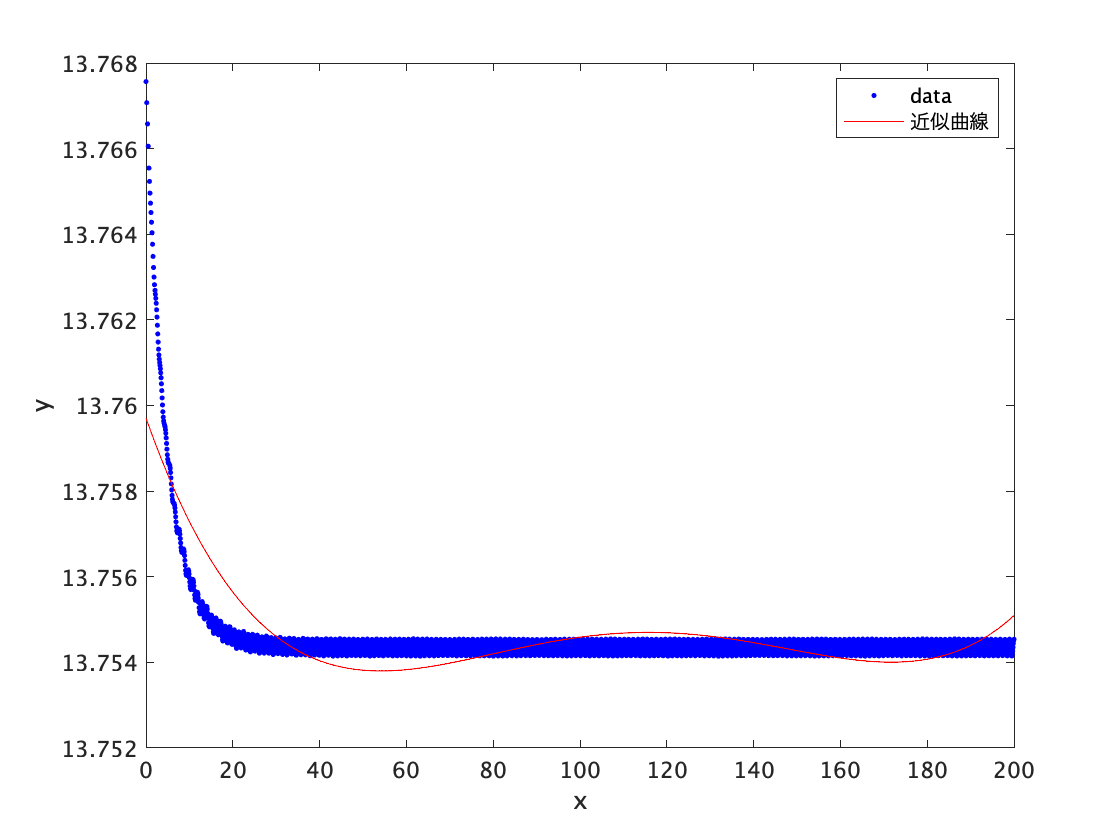


plot(f,t_U(:,1),t_U(:,2))